clc;
clear all;
close all;
clearvars;
warning('off')
stations={'sheetname'};
filename = 'xlsx location';
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
k=0;
for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));
        
    end
end
for iii=1:276
    avr2(iii,1)=mean(avr(iii:iii+89),1);
end
min_dis=min(avr2(:,1));
max_dis=max(avr2(:,1));


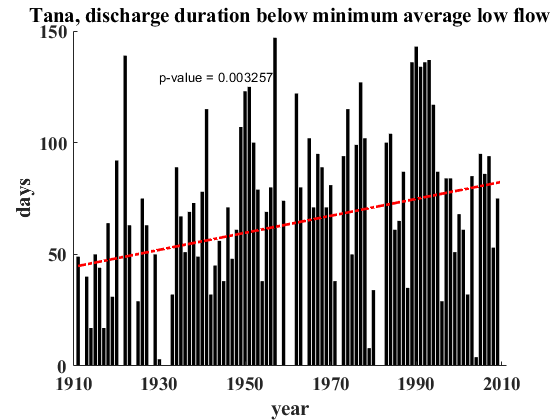

stations={'sheetname'};
filename = 'xlsx location';
[NUM2,TXT2,RAW2] = xlsread(filename,stations{1});
tot_per= floor(size(NUM2,1)/365);
k=1;
for jjj=1:tot_per
            clear seq L_values seq_modified2 seq_modified seq_temp seq_temp2
            A(:,1) = NUM2(k:jjj*365,1);
            A(:,2) = NUM2(k:jjj*365,2);
            
          

           

            consenums = find(A(:,2)<=min_dis);
           if size(consenums,1)==0
           min_days(jjj,1)=0;    

else 

            consenums=consenums' ;  %  array of consecutive numbers
            consenums(end+1)=2 ;  % adds new endpoint to very end of A so code picks up end of last group of consecutive values
            I_1=find(diff(consenums)~=1);  % finds where sequences of consecutive numbers end
            [m,n]=size(I_1);   % finds dimensions of I_1 i.e. how many sequences of consecutive numbers you have
            startpoint=1;    % sets start index at the first value in your array
            seq=cell(1,n) ; % had to preallocate because without, it only saved last iteration of the for loop below
                       % used n because this array is a row vector
                for i=1:n
                    End_Idx=I_1(i);   %set end index
                    seq{i}=consenums(startpoint:End_Idx);  %finds sequences of consecutive numbers and assigns to cell array
                    startpoint=End_Idx+1;   %update start index for the next consecutive sequence
                end

            [row,col]=size(seq);
        

                    seq_modified2=seq;
                    for i2=1:col
                        L_values(1,i2) = length(seq_modified2{i2});
                    end 
%                 end 
                   
         

duration = max(L_values); 
min_days(jjj,1)=duration;    
            end
k=k+365;
end
year_numbers=[1:tot_per]';
bar(year_numbers(:,1),min_days(:,1),'EdgeColor','none','FaceColor',[0 0 0]);
P=polyfit(year_numbers(:,1),min_days(:,1),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'r-.','LineWidth',2);
xlabel('year')
ylabel('days')
% title('Tana, discharge duration below minimum average low flow')
set(gca,'FontSize',14,'FontWeight','Bold','FontName','Times New Roman','XTickLabel',...
    {'1910','1930','1950','1970','1990','2010'})
% ylim([130 250]);
box('off')
V_Pol=min_days(:,1);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol);
text1=['p-value = ' num2str(p_value_Pol)];
text(20,130,text1)